ns6toMUA

% frompreProcessNeuralData_IOT -- used in VSS2022 analysis

% Desired output is an IDX matrix

clear
setup_IOT('BrockHome')

ans = 'S:\bmcBRFS dataset\'

%% Setup File(s) to read

global RIGDIR
cd(RIGDIR)
fileList = dir('**/*.ns6')

fileList = 183×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


name = {fileList.name}.';
idx_bmcBRFSfiles = contains(name,'bmcBRFS');
numberOfFiles = sum(idx_bmcBRFSfiles);
fileNameList = name(idx_bmcBRFSfiles);
folder = {fileList.folder}.'

folder = 183×1 cell array
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211008_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211009_B'}
    {'S:\bmcBRFS dataset\211012_B'}
    {'S:\bmcBRFS dataset\211012_B'}
    {'S:\bmcBRFS dataset\211012_B'}
    {'S:\bmcBRFS dataset\211012_B'}
  

folderNameList = folder(idx_bmcBRFSfiles);
bmcBRFSfileLocation = cell(13,1);
for i = 1:length(fileNameList)
    bmcBRFSfileLocation{i} = strcat(folderNameList{i},filesep,fileNameList{i});
end


## Main Loop

for i = 13:length(bmcBRFSfileLocation)
    warning('starting at session number 11')
    if i == 2
        % bmcBRFS001 has no data. bmcBRFS002 is the real recording for
        % 211009_B
        continue
    end
fullFileName = bmcBRFSfileLocation{i}(1:end-4);
cd(folderNameList{i})

%% findTimePoints

% from STIM = brfsTP(filelist);

STIM = findTimePoints(fullFileName);
STIM.fullFileName = fullFileName;
STIM.localFileName = fullFileName(end-18:end);


%% alignToPhotoTrigger

trigger = 'custom';

bhvFile = strcat(fullFileName,'.bhv2');
[data, MLConfig, TrialRecord, filename] = mlread(bhvFile);
% % % %     PixelsPerDegree = MLConfig.PixelsPerDegree;
% % % %     ScreenResolution = MLConfig.Resolution;
% % % %     BehavioralCodes = TrialRecord.TaskInfo.BehavioralCodes;
% % % %      bhv = concatBHV(filename) %runs, but does not create resolution or ppd necessary

TP = STIM.tp_sp;
[newTP,trigger] = photoReTriggerSTIM_2021(TP,fullFileName,0,trigger);
%%% --> BMC and blake - photoReTriggerSTIM is an example of a code that
%%% would benefit from editing errors (or exclusions) out of existance

STIM.tp_pt = newTP;



%% trialAlignNeuralData

% diNeuralDat has turned into trialAlignData_IOT
    %You need to obtain STIM.ellabels. This is generated in diV1Lim code
    %(something that is an antiquated function form ephys analysis). I need
    %to figure out how to openNEV for el_labels
        win_ms    = [50 100; 150 300; 150 800; -50 0]; % ms;

[RESP, win_ms, SDF, sdftm, PSTH, psthtm] = trialAlignData_IOT(STIM,'mua',true,win_ms);


% Save your output -- approx 225 MB

NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


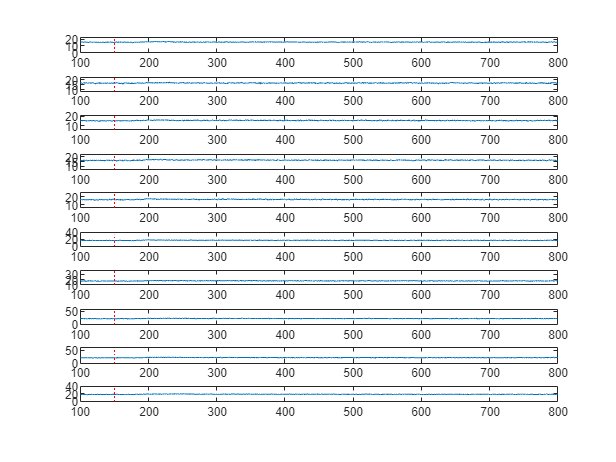

NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


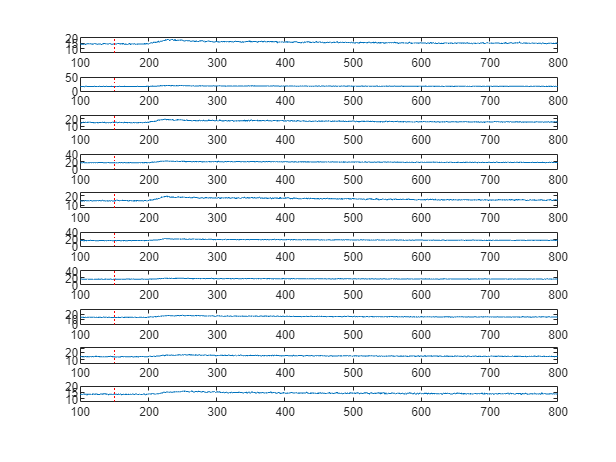

NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


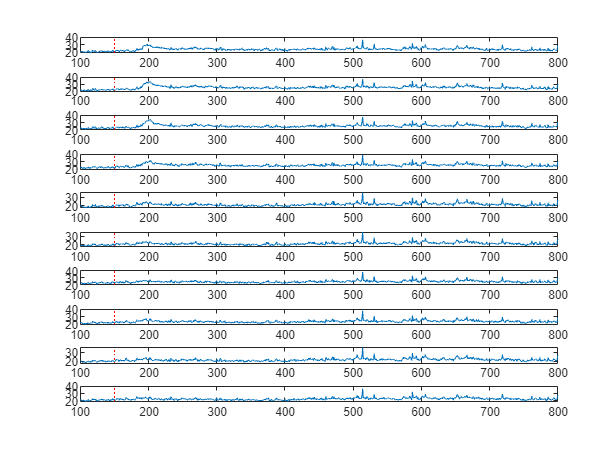

NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


NOTE: Reading the header information only. To read the data use with parameter 'read': openNSx('read')


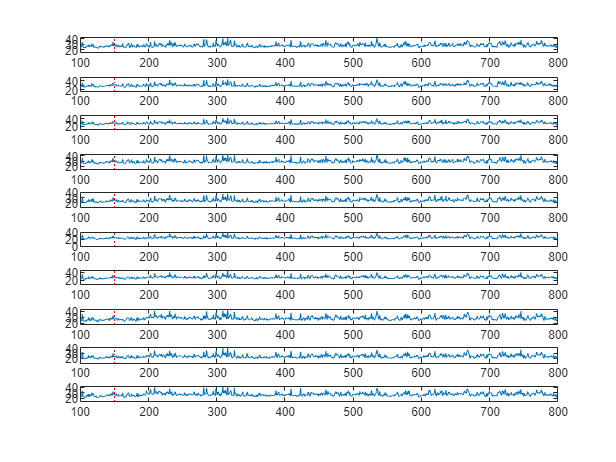

trialAlignedMUAPacket.RESP = RESP;
trialAlignedMUAPacket.win_ms = win_ms;
trialAlignedMUAPacket.SDF = SDF;
trialAlignedMUAPacket.sdftm = sdftm;
trialAlignedMUAPacket.PSTH = PSTH;
trialAlignedMUAPacket.psthtm = psthtm;
trialAlignedMUAPacket.STIM = STIM;

global OUTDIR_FD
cd(OUTDIR_FD)
saveFileName = strcat(OUTDIR_FD,STIM.localFileName ,'_FD.mat');
save(saveFileName,"trialAlignedMUAPacket");

%% Test - plot one line from your data (this sould access Vis)
% This is the first time we have seen BRFS photo-diode triggered data
figure
for sp = 1:10
    subplot(10,1,sp)
    holder = SDF(sp+20,:,:);
    holder2 = squeeze(holder);
    holder3 = nanmean(holder2,2);
    plot(holder3)
    vline(150)
    xlim([100 800])
end

end